% Jep Brinkmann Thesis HMM example
clc; close all;

Initiate the HMM

k = number of states

d = number of possible observational values

T = transition matrix

O = emission matrix

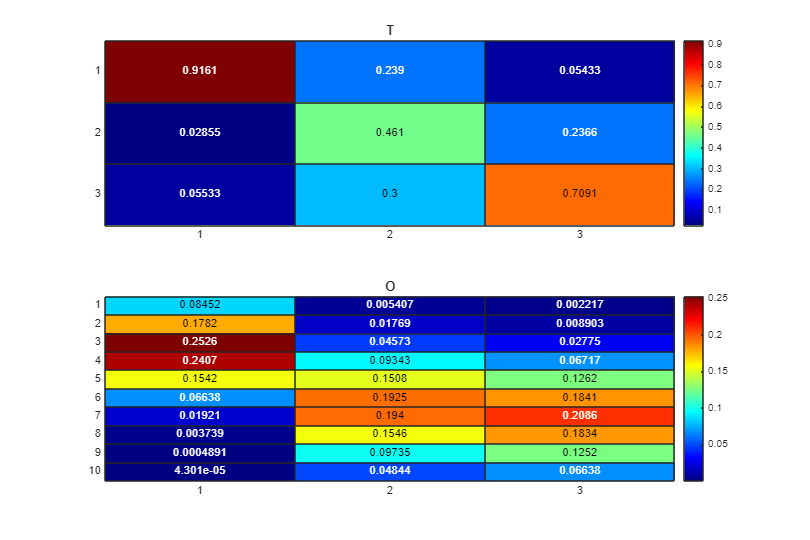

k = 3;
d = 10;
lam = 5;

T = lam * eye(k) + abs(randn(k, k));
T = Stochasticize(T);

O = initialize_emission_matrix(d, k, 1);

% k = 2;
% d = 6;
% 
% T = [.9 .1; .05 .95];
% 
% O = [1/6, 1/6, 1/6, 1/6, 1/6, 1/6;...
% 7/12, 1/12, 1/12, 1/12, 1/12, 1/12];

% 
% k = 3;
% d = 10;
% 
% T = [8/10, 1/15, 1/6; 
%     1/10, 13/15, 1/6; 
%     1/10, 1/15, 2/3];
% 
% O = [6/15, 1/20, 1/50;
%     1/15, 11/20, 1/50;
%     1/15, 1/20, 1/50;
%     1/15, 1/20, 21/50;
%     1/15, 1/20, 21/50;
%     1/15, 1/20, 1/50;
%     1/15, 1/20, 1/50;
%     1/15, 1/20, 1/50;
%     1/15, 1/20, 1/50;
%     1/15, 1/20, 1/50;]';

% k = 3;
% d = 8;
% 
% T = [8/10, 1/15, 1/6; 
%     1/10, 13/15, 1/6; 
%     1/10, 1/15, 2/3];
% 
% O = [6/15, 1/20, 1/50;
%     1/15, 11/20, 1/50;
%     1/15, 1/20, 1/50;
%     1/15, 1/20, 21/50;
%     1/15, 1/20, 21/50;
%     1/15, 1/20, 1/50;
%     1/15, 1/20, 1/50;
%     3/15, 3/20, 3/50;];

figure('Renderer', 'painters', 'Position', [10 10 900 600])

subplot(2, 1, 1);
h = heatmap(T, Colormap=jet());
h.Title = 'T';

subplot(2, 1, 2);
h = heatmap(O, Colormap=jet());
h.Title = 'O';

eig(T)

ans =     1.0000
    0.7944
    0.2918


Generate an observational sequence based on the defined HMM

T_seq = 1e5;

[seq,states] = hmmgenerate(T_seq,T',O');

% U{1} = (O' * T);
% U{2} = O';
% U{3} = (O' * T');
% 
% P3 = cpdgen(U);
% 
% [V, D, W] = eig(T);
% mu = abs(W(:, 1));
% mu = mu ./ sum(mu);
% P2 = O' * T * diag(mu) * O;

Generate Probability Density Tensors

tic
P3 = ProbabilityTensorGenerate(seq, 3, d);
P2 = ProbabilityTensorGenerate(seq, 2, d);
toc

Elapsed time is 0.856682 seconds.




warning('on', 'all')

rho = 0: 0.01 : 1;
iter = 1:length(rho);

gamma = 0.5;

max_iters = 1000;

Cost = zeros(1, length(iter));

for i = progress(iter)
    [B1, B2, B3, B4, output] = admm_tensor_factorization(P3, P2, k, rho(i), gamma, max_iters);

    Cost(i) = output.relerr(end);
end

Processing:  000%  |                                      | 0/101it [00:00:00<Inf:NaN:NaN, Inf it/s]


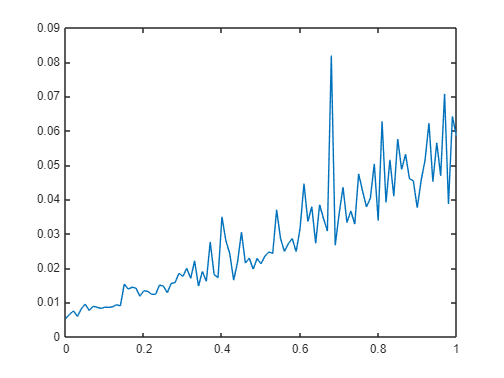

% filteredCost = [];
% for i = 1:length(Cost)
%     if(Cost(i) > 1.6 + (i/length(Cost)))
%         filteredCost = [filteredCost Cost(i)];
%     end
% end
% 
% filteredIndex = find(Cost > 1.6);

figure();
plot(linspace(0, 1, length(Cost)), Cost)


minJ = min(Cost);
minIndex = find(Cost==minJ);


tic
[B1, B2, B3, B4, output] = admm_tensor_factorization(P3, P2, k, rho(i), gamma, max_iters)

B1 =     0.1434    0.1693    0.2136
    0.1872    0.0585    0.0465
    0.0373    0.0003    0.0850
    0.1330    0.1867    0.1582
    0.0144    0.0253    0.1906
    0.1020    0.0156    0.1636
    0.0577    0.2124    0.0442
    0.0631    0.1430    0.0170
    0.0232    0.1063    0.0802
    0.2388    0.0827    0.0011


B2 =     0.2123    0.0094    0.0339
    0.2629    0.0116    0.0420
    0.0352    0.2075    0.0475
    0.0029    0.0029    0.2528
    0.0063    0.0025    0.1934
    0.0030    0.0030    0.2656
    0.0158    0.0881    0.0941
    0.3516    0.0155    0.0562
    0.0837    0.5013    0.0109
    0.0264    0.1582    0.0034


B3 =     0.1451    0.1380    0.0762
    0.0014    0.1222    0.1715
    0.1153    0.0392    0.1228
    0.0374    0.1087    0.1543
    0.0737    0.0853    0.0452
    0.1788    0.1263    0.0009
    0.1941    0.0197    0.1468
    0.0021    0.3418    0.0132
    0.1730    0.0013    0.1142
    0.0790    0.0173    0.1551


B4 =     0.0687    0.0556    0.8988
    0.9164    0.9294    0.0739
    0.0149    0.0150    0.0274


output = struct with fields:
    relerr: [0.0212 0.0308 0.0383 0.0403 0.0388 0.0394 0.0398 0.0406 0.0414 0.0423 0.0432 0.0440 0.0445 0.0451 0.0457 0.0463 0.0469 0.0474 0.0479 0.0482 0.0484 0.0486 0.0489 0.0491 0.0493 0.0496 0.0499 0.0501 0.0504 0.0506 0.0509 … ] (1×1000 double)


toc

Elapsed time is 0.169141 seconds.



B1 = Stochasticize(B1);
B2 = Stochasticize(B2);
B3 = Stochasticize(B3);
B4 = Stochasticize(B4);

P_best = PermutationFitEmission(O, B2);

B1 = B1 * P_best';
B2 = B2 * P_best';
B3 = B3 * P_best';
B4 = P_best * B4 * P_best';

T_hat = Stochasticize(pinv(B2) * B3);
T_hat = P_best * T_hat * P_best';


norm(T-B4, "fro") + norm(O-B2, "fro")

ans = 2.2827

norm(T-T_hat, "fro") + norm(O-B2, "fro")

ans = 2.0314

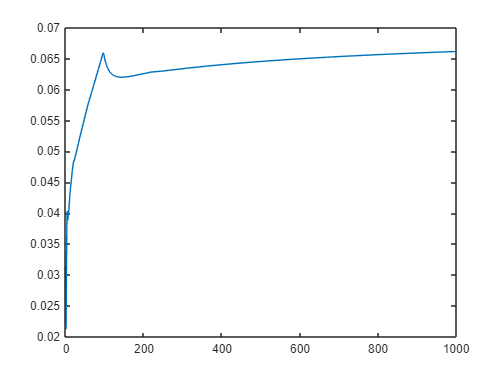


figure()
plot(output.relerr)

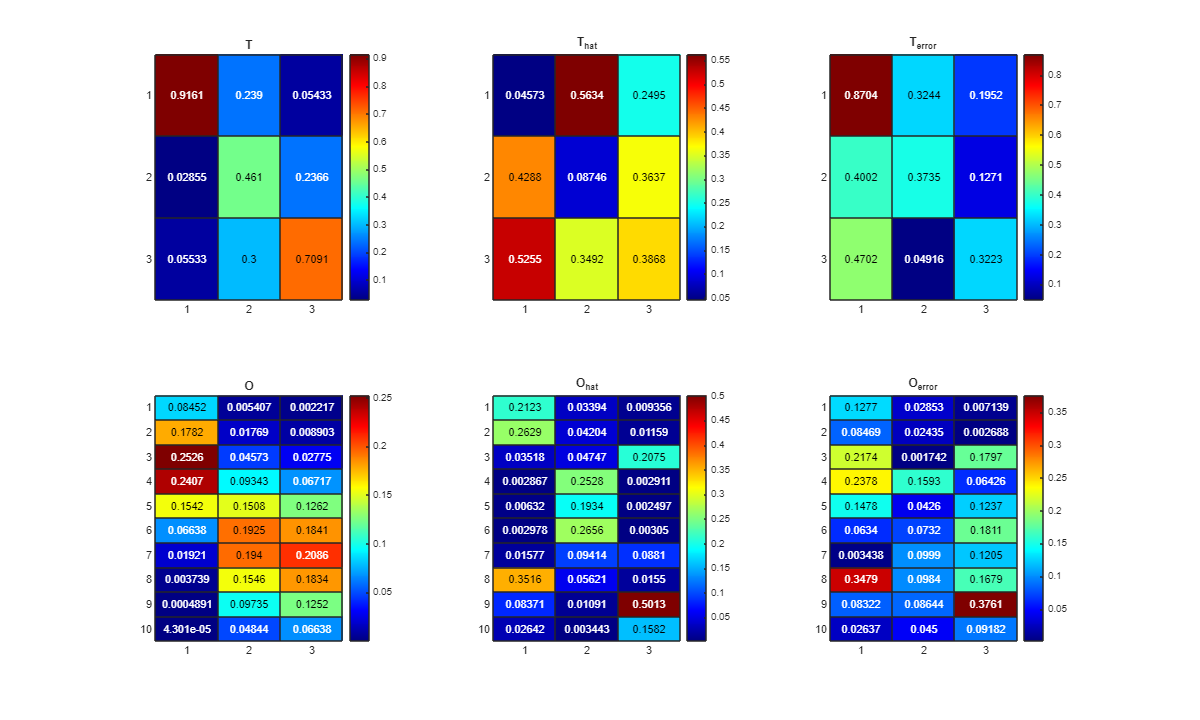


plotHMMError(T, T_hat, O, B2)